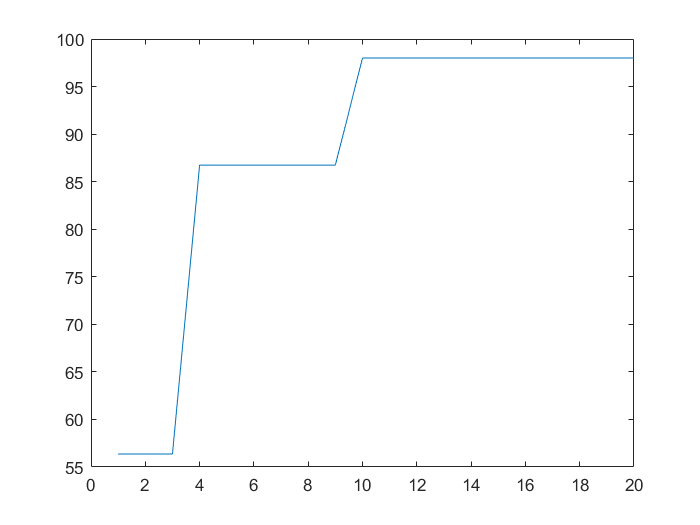

clc;
clear all;
format long; %设定数据显示格式
%初始化参数
T=20; %仿真代数
N=4;  %群体规模
pm=0.05;
pc=0.8;   % 交叉变异概率
umax=7;
umin=1;   %参数取值范围
L=3;      %单个参数字串长度，总编码长度2L
bval=round(rand(N,2*L));  %初始种群
bestv=-inf; %最优适应度初值
 
%迭代开始
for ii=1:T
    
%解码，计算适应度
    for i=1:N
        y1=0;y2=0;
        for j=1:1:L
            y1=y1+bval(i,L-j+1)*2^(j-1);
        end
        x1=(umax-umin)*y1/(2^L-1)+umin;
        for j=1:1:L
            y2=y2+bval(i,2*L-j+1)*2^(j-1);
        end
         x2=(umax-umin)*y2/(2^L-1)+umin;
         obj(i)=x1.^2+x2.^2; %目标函数
         xx(i,:)=[x1,x2];
    end
func=obj; %目标函数转换为适应度函数
p=func./sum(func);
q=cumsum(p); % 累加
[fmax,indmax]=max(func); %求当代最佳个体
    if fmax>=bestv
        bestv=fmax; %到目前为止最优适应度值
        bvalxx=bval(indmax,:); %到目前为止最佳位串
        optxx=xx(indmax,:);% 到目前为止最优参数
    end
    Bfit1(ii)=bestv; %存储每代的最优适应度
%遗传操作开始
%轮盘赌选择
for i=1:(N-1)
    r=rand;
tmp=find(r<=q);
    newbval(i,:)=bval(tmp(1),:);
end
newbval(N,:)=bvalxx;  %最优保留
bval=newbval;
%单点交叉
for i=1:2:(N-1)
    cc=rand;
    if cc<pc
        point=ceil(rand*(2*L-1)); %取得一个1到2L-1的整数
        ch=bval(i,:);
bval(i,point+1:2*L)=bval(i+1,point+1:2*L);
        bval(i+1,point+1:2*L)=ch(1,point+1:2*L);
    end
end
bval(N,:)=bvalxx; %最优保留
%位点变异
mm=rand(N,2*L)<pm; %小于变异概率赋值为1，其它复制为0
mm(N,:)=zeros(1,2*L); %最后一行不变异，强制赋0
bval(mm)=1-bval(mm);
end
%输出
plot(Bfit1);

bestv          %输出最优适应度值

bestv =     98


optxx          %输出最优参数

optxx =      7     7
